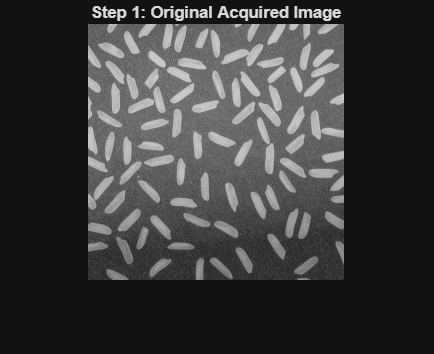

full_path = which('rice.png');
img = imread(full_path);

figure;
imshow(img);
title('Step 1: Original Acquired Image');

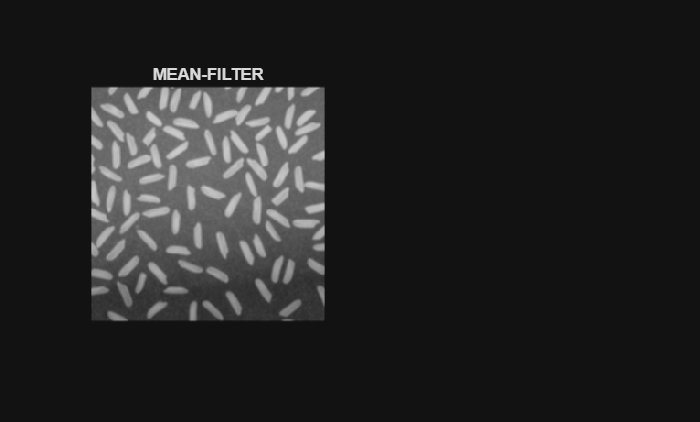

h_mean = fspecial("average",[3,3]);
img_mean = imfilter(img,h_mean);
figure;
    subplot(1,2,1);
        imshow(img_mean);
        title("MEAN-FILTER");

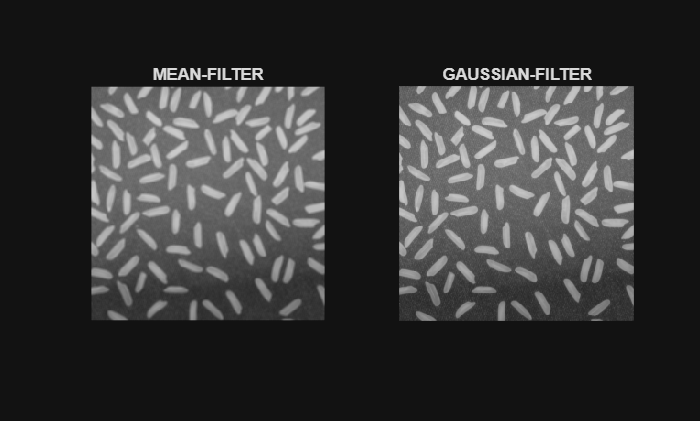

h_gaussian = fspecial("gaussian", [3, 3], 0.5);
img_gaussian = imfilter(img, h_gaussian);
subplot(1,2,2);
imshow(img_gaussian);
title("GAUSSIAN-FILTER");

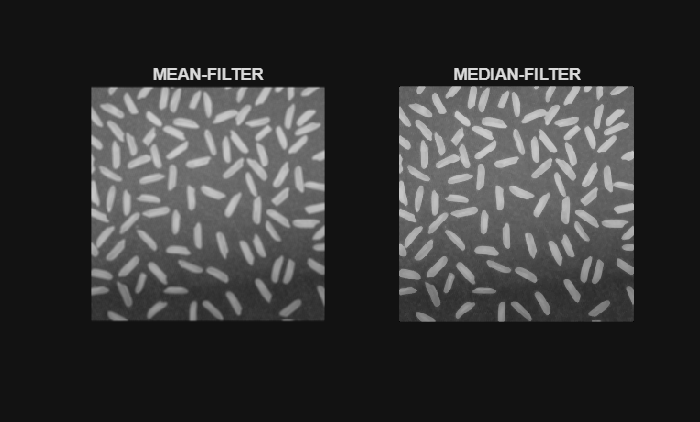

img_median = medfilt2(img);
subplot(1,2,2);
    imshow(img_median);
    title("MEDIAN-FILTER");

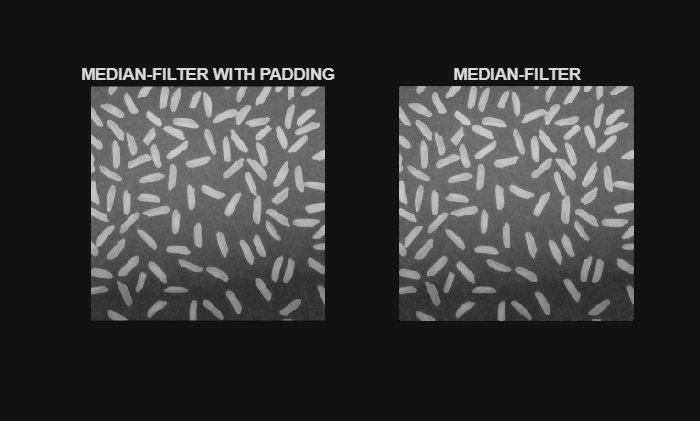

img_med_pad = medfilt2(img, [3 3], "symmetric");
subplot(1,2,1);
imshow(img_med_pad);
title("MEDIAN-FILTER WITH PADDING");

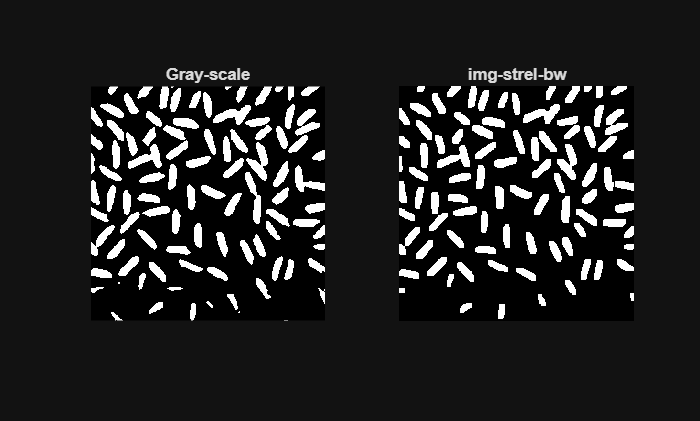

th = graythresh(img_med_pad);
img_bw = imbinarize(img_med_pad,th);
se = strel("disk",3);
img_strel = imopen(img_bw,se);
close all;
figure ;
    subplot(1,2,1);
        imshow(img_bw);
        title("Gray-scale");
    subplot(1,2,2);
        imshow(img_strel);
        title("img-strel-bw");

cc = bwconncomp(img_strel);
stat = regionprops(cc,"Area","Centroid");

number_obj = cc.NumObjects;
fprintf("we have %d rices",number_obj);

we have 88 rices

close all;
histogram([stat.Area], 50);
title('Histogram of Blob Areas');
xlabel('Area (in pixels)');

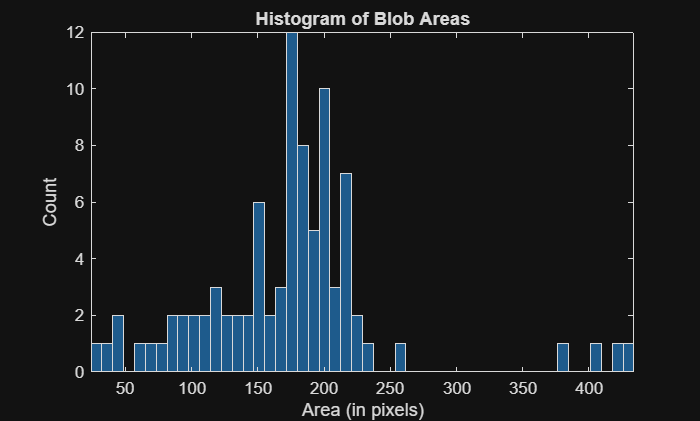

ylabel('Count');
axis tight;

ทำให้ดีขึ้น

min_area_thresh = 30;
stat_clean = stat([stat.Area] > min_area_thresh);
num_rice_clean = length(stat_clean);
disp(num_rice_clean);

    87



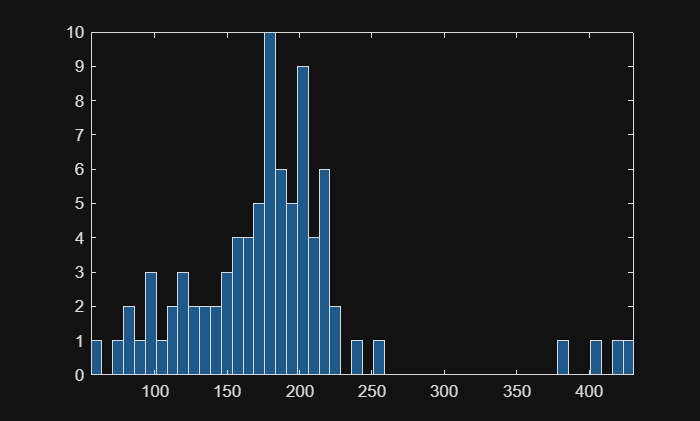

close all;
figure;
    histogram([stat_clean.Area],50);
    axis tight;

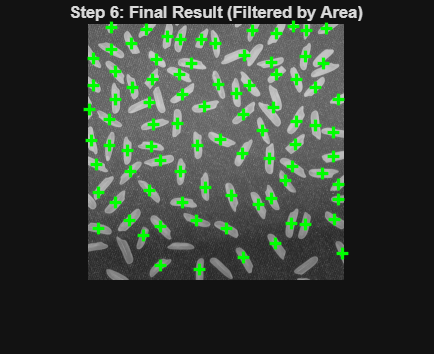

figure;
imshow(img); % Show the original 'img' from Step 1
title('Step 6: Final Result (Filtered by Area)');
hold on;

% Loop through only the CLEAN blobs
for i = 1:num_rice_clean
    plot(stat_clean(i).Centroid(1), stat_clean(i).Centroid(2), "g+", 'MarkerSize', 7, 'LineWidth', 2);
end
hold off;